Variational Gaussian Process

takes a mean function a kernel object and a list of inducing points

Training uses a mini-batch stochastic optimization.

clear all
%close all
clc

f1 = @(x) (6*x-2).^2.*sin(12*x-4);

xx = linspace(0,1,100)';
yy = f1(xx);

x1 = lhsdesign(500,1);
y1 = f1(x1);
y1 = y1 + normrnd(0,0*y1 + 0.8);

ma = means.const(2)+means.linear(6)

ma =   const with properties:

         meanz: {[1×1 means.const]  [1×1 means.linear]}
        coeffs: {[2]  [6]}
    operations: {'+'}


a = kernels.Matern52(1,0.2);

a.signn = 0.5;

Z = VGP(ma,a,linspace(0,1,5)');

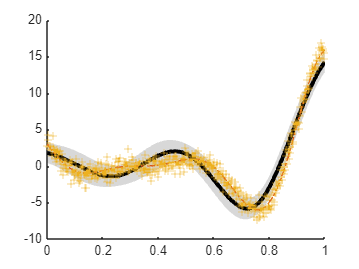

Z1 = Z.condition(x1,y1);

figure
hold on
utils.plotLineOut(Z1,1,1)
plot(xx,yy,'-.')
plot(x1,y1,'+')

tic
[Z2,LL] = Z1.train(1);
toc

Elapsed time is 1.253434 seconds.


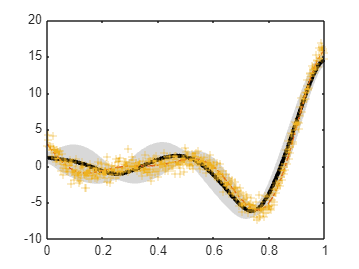

figure
utils.plotLineOut(Z2,1,1)
hold on
plot(xx,yy,'-.')
plot(x1,y1,'+')

opts = bads('Defaults');
opts.Display = 'final';

for i = 1:5
    xn = bads(@(x) Z2.newXuDiff(x),rand(),0,1,0,1,[],opts);
    Z2 = Z2.addInducingPoints(xn);
end

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -7.24913.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -7.9529.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -6.1953.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -4.16816.

Beginning optimization of a DETERMINISTIC objective fcn.

Optimization terminated: change in the function value less than OPTIONS.TolFun.
Function value at minimum: -1.46678.



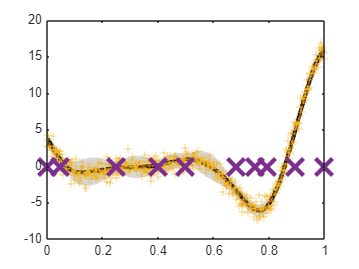


[ys,sig] = Z2.eval(xx);

figure
utils.plotLineOut(Z2,1,1)
hold on
plot(xx,yy,'-.')
plot(x1,y1,'+')
plot(Z2.Xu,0*Z2.Xu,'x','MarkerSize',18,'LineWidth',3)

tic
[Z3,LL] = Z2.train(1);
toc

Elapsed time is 1.306064 seconds.


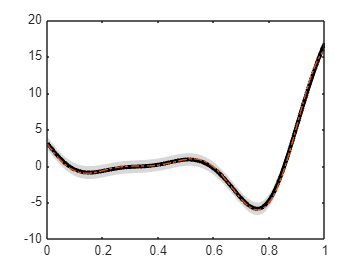


figure
utils.plotLineOut(Z3,1,1)
hold on
plot(xx,yy,'-.')

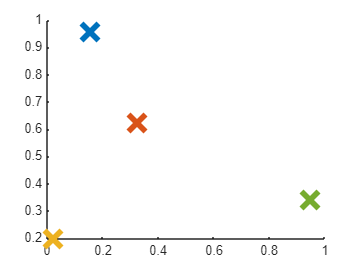

figure
hold on
tic
for i = 1:5
    [x{i},R{i}] = BO.argmax(@BO.maxVAR,Z2);
    plot(x{i},R{i},'x','MarkerSize',18,'LineWidth',4)
end
xlim([0 1])

toc

Elapsed time is 1.417703 seconds.
